# ** ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_cs.mlx
    -----------
    This code solves a simplified partial equilibrium version of the model in Cubas and Silos (IER, 2020).

%}

## Model: Occupational Choice Model with Progressive Taxation.

Workers are live up to age $T$ and can choose among one of $J$ occupations, which differ in riskiness, to work in and earn a wage, $w_j$. They accumulate human capital, $z$, which is subject to shocks. Labor income is taxed progressively and after-tax income is consumer completely. A worker can choose to stay in her current occupation or switch to another one. When switching, workers incur a cost, $c$, representing a loss in human capital. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T}}{\text{max }} U =  \sum_{t=1}^{T} \beta^{t-1} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } c_t = \lambda y_t^{1-\phi}  \ , $$



$$y_t = w_je^{z_t + \epsilon_t - c(t,\kappa_0,\kappa_1,\kappa_2)} \ ,$$



$$c(t,\kappa_0,\kappa_1,\kappa_2)  = \kappa_0 + \kappa_1 t + \kappa_2 t^2  \ ,$$



$$\text{log} \ z_{t+1} = \text{log} \ z_t + \text{log} \ \epsilon_t \ ,$$



$$\text{log} \ \epsilon_{t+1} \sim \mathcal{N}(0,\sigma_{\epsilon}^2) \ ,$$



$$c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$.

## Recursive Formulation.

Dropping the time subscripts, the recursive formulation of the worker's problem is


$$V(z,\epsilon,j) = \underset{j}{\text{max}}\left\{V^{\text{stay}}(z,\epsilon,j),V^{\text{switch}}(z,k)_{k\neq j}\right\} \ ,$$


where $k$ is an occupation different from the current one. The value of staying is

   
$$V^{stay}(z,\epsilon,j) = \frac{c^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}\left[V(z',\epsilon',j)\right] \ ,$$
 

 
$$\text{s.t. } c = \lambda y^{1-\phi}  \ , $$



$$y = w_je^{z + \epsilon} \ ,$$



$$\text{log} \ z' = \text{log} \ z + \text{log} \ \epsilon \ ,$$



$$\text{log} \ \epsilon' \sim \mathcal{N}(0,\sigma_{\epsilon}^2) \ ,$$



$$c > 0 \ .$$


The value of switching to new occupation is

   
$$V^{switch}(z,\epsilon,k) = \mathbb{E}\left\{\frac{c^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}\left[V(z',\epsilon',k)\right]\right\} \ ,$$
 

 
$$\text{s.t. } c = \lambda y^{1-\phi}  \ , $$



$$y = w_ke^{z + \epsilon - c(t,\kappa_0,\kappa_1,\kappa_2)} \ ,$$



$$c(t,\kappa_0,\kappa_1,\kappa_2)  = \kappa_0 + \kappa_1 t + \kappa_2 t^2  \ ,$$



$$\text{log} \ z' = \text{log} \ z + \text{log} \ \epsilon \ ,$$



$$\text{log} \ \epsilon' \sim \mathcal{N}(0,\sigma_{\epsilon}^2) \ ,$$



$$c > 0 \ ,$$


where the outer-most expectation is over $\left\{\epsilon_i\right\}_{i=1}^N$. 

## Normalization.

Because human capital is not stationary but we have CRRA utility, we can normalize the value functions by human capital and eliminate $z$ as a state variable. The value functions become

   
$$V^{stay}(\epsilon,j) = e^{(1-\sigma)(1-\phi)\epsilon}\frac{c^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}\left[V(\epsilon',j)\right] \ ,$$
 

 
$$\text{s.t. } c = \lambda y^{1-\phi}  \ , $$



$$y = w_je^{\theta_j} \ ,$$



$$\text{log} \ \epsilon' \sim \mathcal{N}(0,\sigma_{\epsilon}^2) \ ,$$



$$c > 0 \ ,$$


   
$$V^{switch}(\epsilon,k) = \mathbb{E}\left\{e^{(1-\sigma)(1-\phi)\epsilon}\frac{c^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}\left[V(\epsilon',k)\right]\right\} \ ,$$
 

 
$$\text{s.t. } c = \lambda y^{1-\phi}  \ , $$



$$y = w_ke^{- c(t,\kappa_0,\kappa_1,\kappa_2)} \ ,$$



$$c(t,\kappa_0,\kappa_1,\kappa_2)  = \kappa_0 + \kappa_1 t + \kappa_2 t^2  \ ,$$



$$\text{log} \ \epsilon' \sim \mathcal{N}(0,\sigma_{\epsilon}^2) \ ,$$



$$c > 0 \ .$$


See the paper for an explanation.

## Wages.

The model is partial equilibrium but wages are computed as the marginal product of labor in each occupation, assuming labor is the only factor of production,


$$w_j = \alpha_jN_j^{\alpha_j-1}\prod_{k\neq j}N_k^{\alpha_k} \ ,$$


where $N_j$ is the fraction of the population and $\alpha_j$ is labor's share of income for occupation $j$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/datho/Desktop/Xavier code'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is /Users/datho/Desktop/Xavier code 



## Set the parameters and generate the state space.

Calls: model.m.

For simplicity, assume that $J=3$, where each occupation represents safe, average, and risky occupations.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.2900 seconds.


## Plot policy functions.

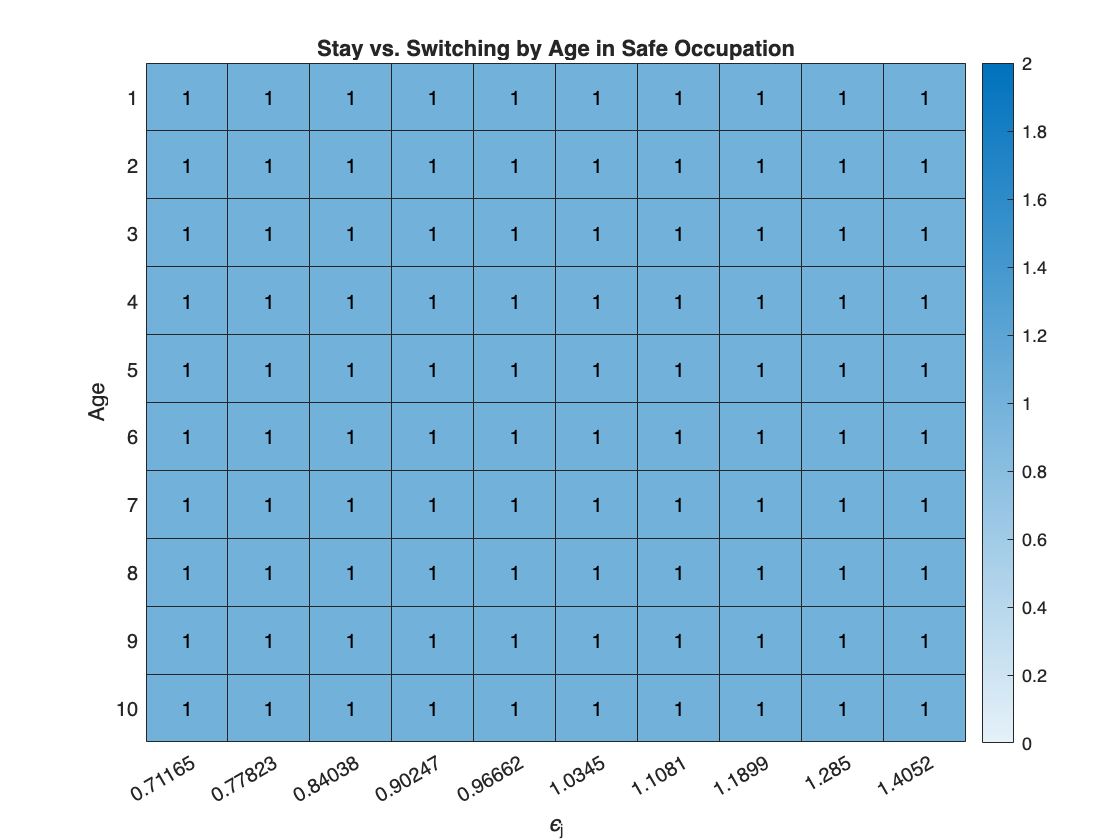

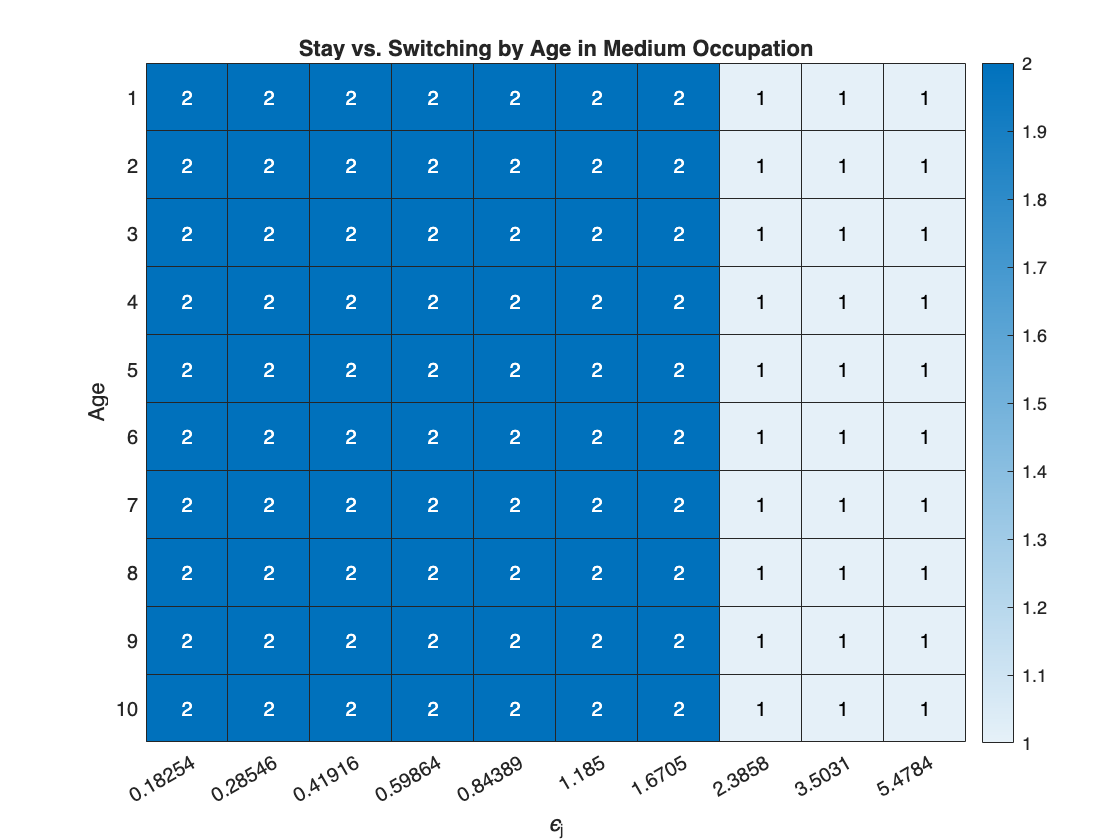

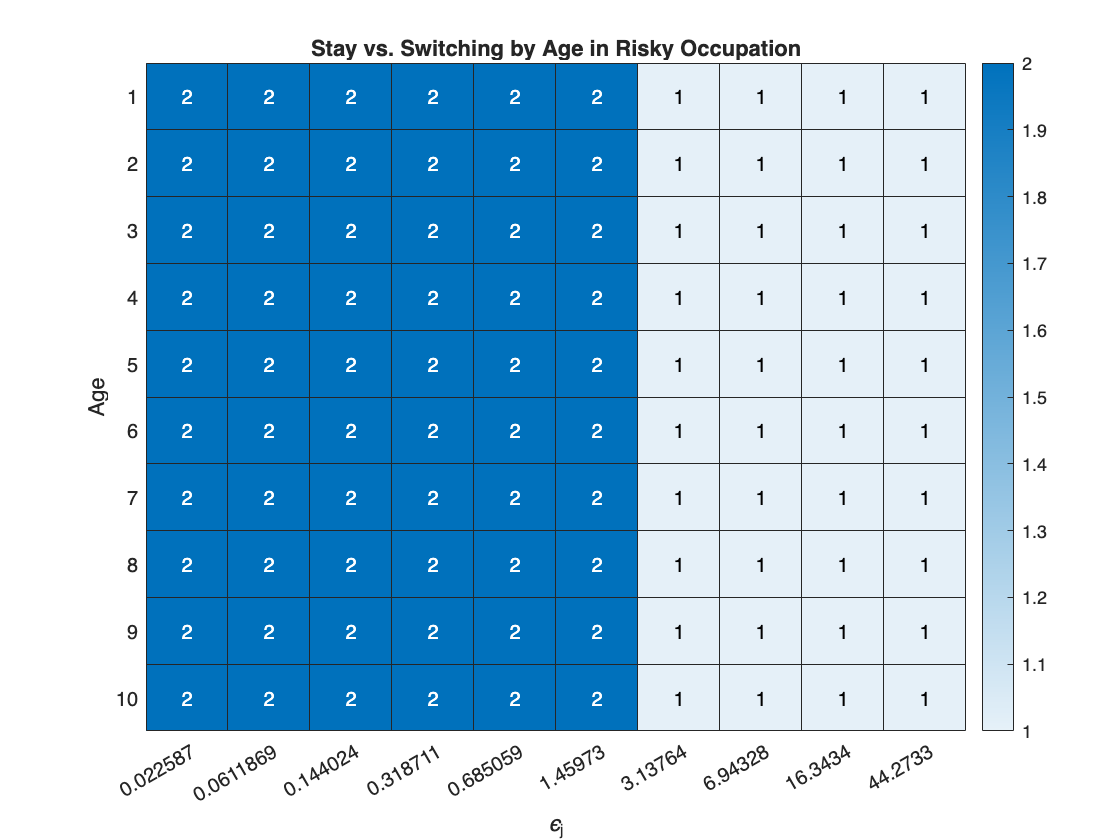

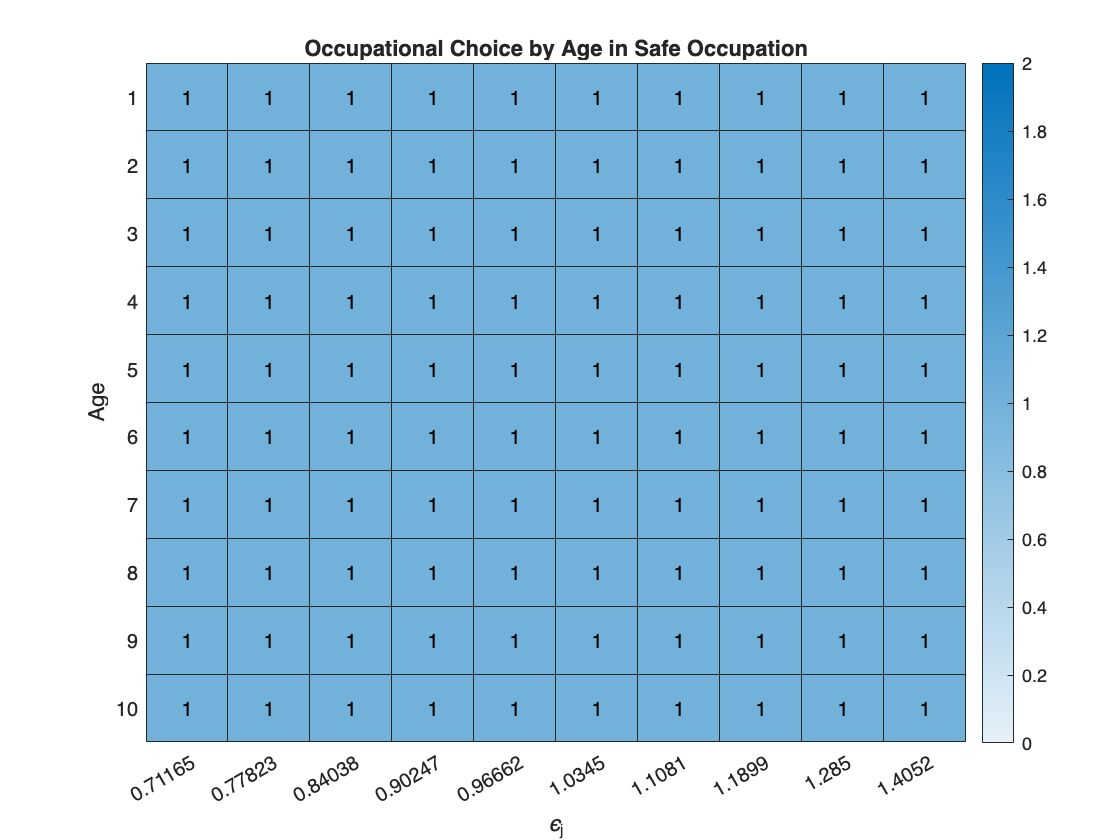

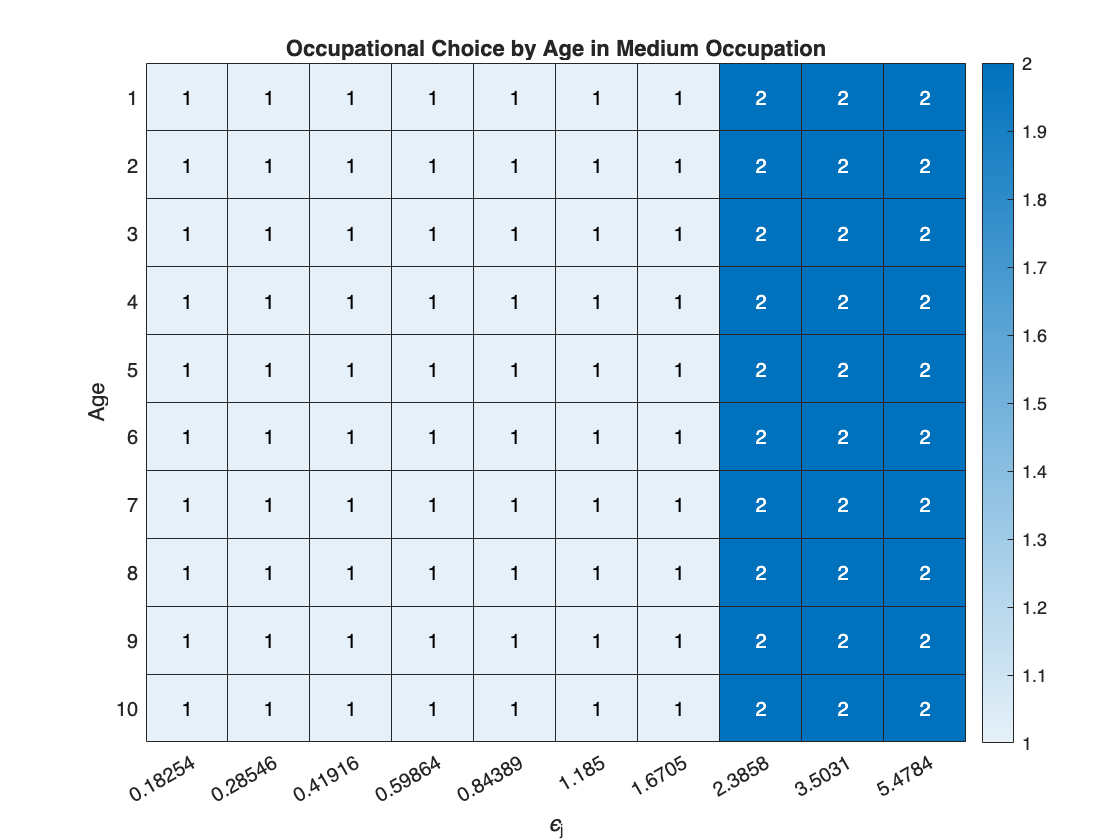

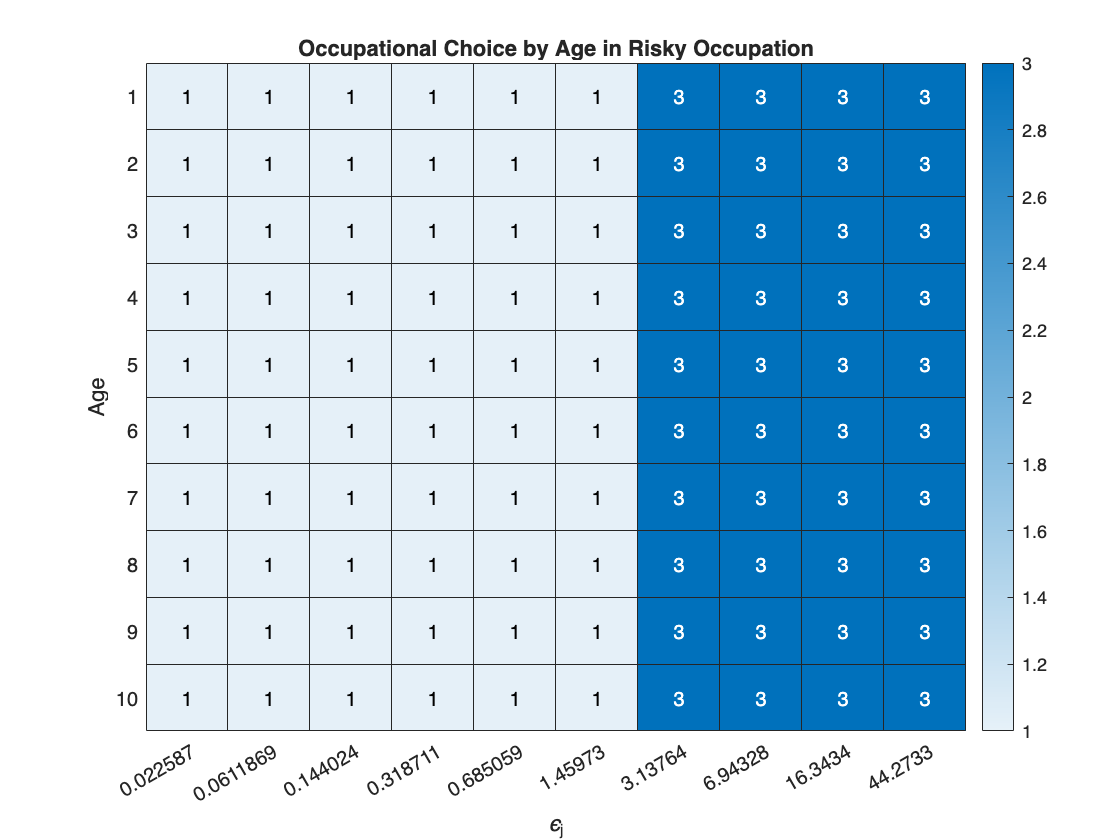

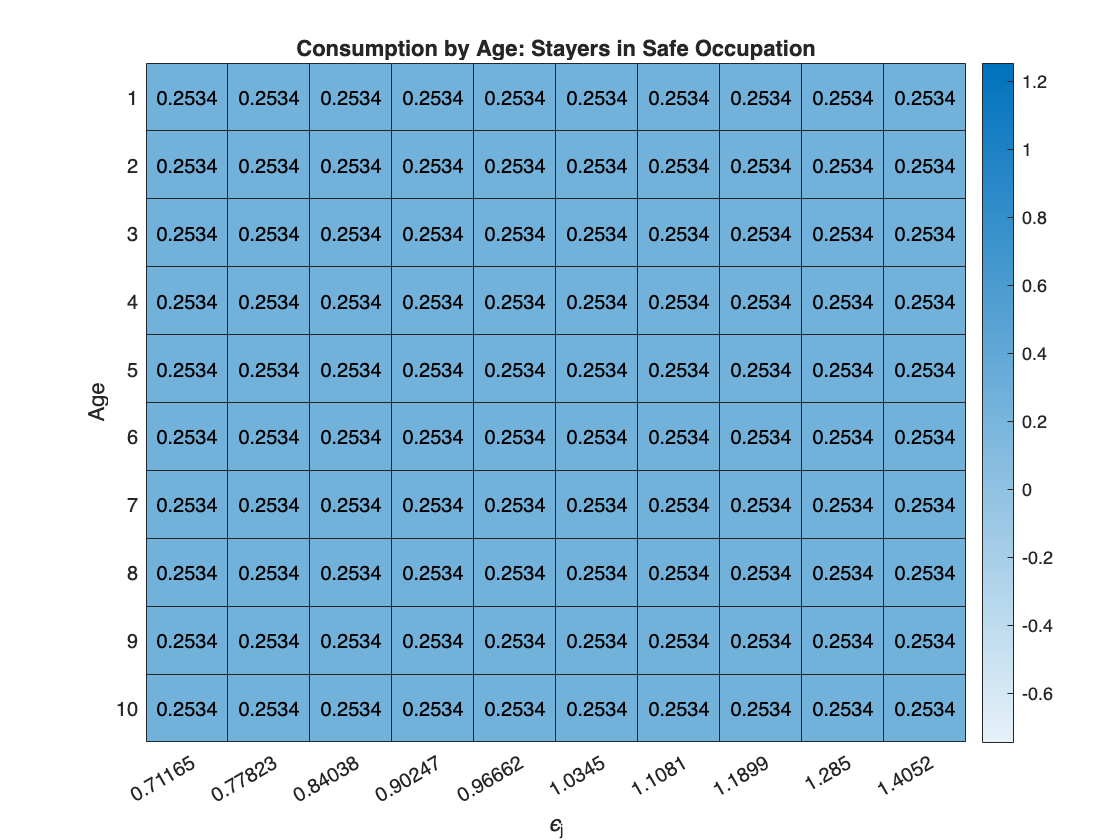

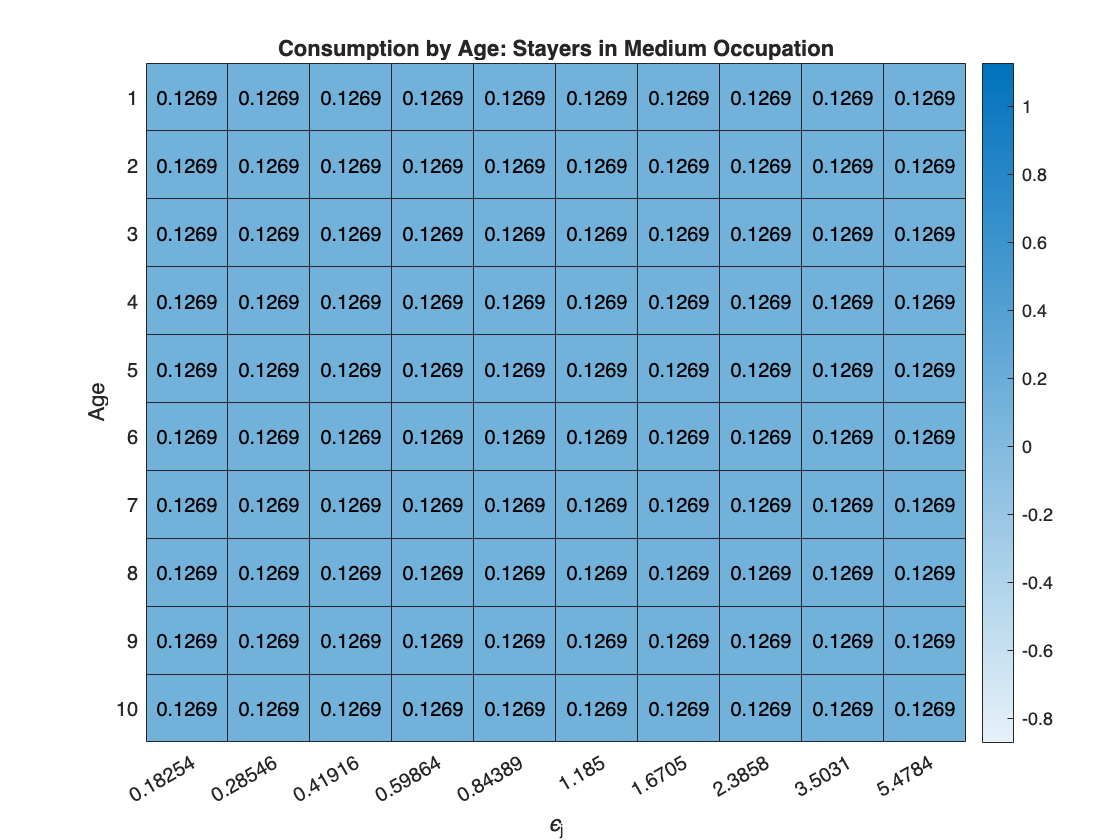

my_graph.plot_policy(par,sol)